# Build an example to illustrate ARCH generation and fitting

## **Step 1: Generate Synthetic Data for an ARCH Model**

ARCH models are used to model financial time series data that exhibit time-varying volatility clustering, meaning periods of swings are followed by periods of relative calm. An ARCH(1) model can be represented as:

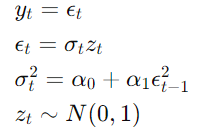

where *y(t)* is the time series, *ϵ(t)* is the error term, *σ**t^*2 is the conditional variance, *α*0 and *α*1 are parameters of the model, and *z(t)* is a standard normal random variable.

MATLAB Code to Generate Synthetic ARCH(1) Data

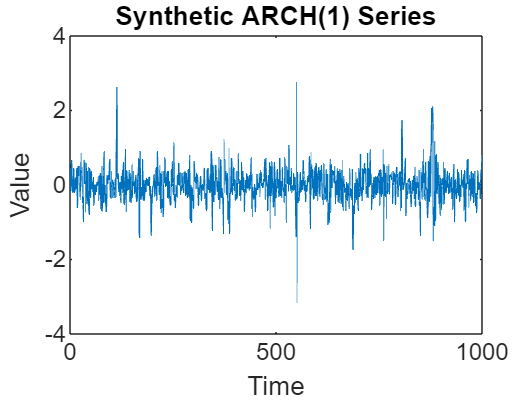

% Parameters
alpha0 = 0.1;
alpha1 = 0.5;
T = 1000; % Number of observations

% Pre-allocate
epsilon = zeros(T,1);
sigmaSquared = zeros(T,1);
y = zeros(T,1);

% Initial values
epsilon(1) = sqrt(alpha0 / (1 - alpha1));
sigmaSquared(1) = alpha0 + alpha1 * epsilon(1)^2;
y(1) = epsilon(1);

% Generate the ARCH(1) series
for t = 2:T
    sigmaSquared(t) = alpha0 + alpha1 * epsilon(t-1)^2;
    epsilon(t) = sqrt(sigmaSquared(t)) * randn;
    y(t) = epsilon(t); % In this simple model, y_t = epsilon_t
end

% Plot the generated series
plot(y);
title('Synthetic ARCH(1) Series');
xlabel('Time');
ylabel('Value');

## **Step #2: Perform the Augmented Dickey-Fuller test**

- If `h = 1`, the test rejects the null hypothesis, suggesting the series **does not have a unit root** and is **stationary**.

- If `h = 0`, the test does not reject the null hypothesis, indicating the **series may have a unit root** and be **non-stationary**.

[h, pValue, stat, cValue] = adftest(y);

% Display the results
disp(['ADF Test Hypothesis (h = 0: Has unit root, h = 1: Stationary): ', num2str(h)]);

ADF Test Hypothesis (h = 0: Has unit root, h = 1: Stationary): 1


disp(['P-value: ', num2str(pValue)]);

P-value: 0.001


disp(['Test Statistic: ', num2str(stat)]);

Test Statistic: -31.3165


disp(['Critical Values: ', num2str(cValue)]);

Critical Values: -1.9416
